8.   Consider the problem

PDE                    $u_{\textrm{tt}} =u_{\textrm{xx}}$                    $0<x<1$,    $t>0$

BCs                     $\left\lbrace \begin{array}{cc}
u\left(0,t\right)=0 & t>0\\
u\left(1,t\right)=0 & t>0
\end{array}\right.$

IC                        $u\left(x,0\right)=\sin \left(\pi x\right)$   $0\le x\le 1$ 

Solve this problem using the method described in class (Implicit FD method) using various values of lambda including $\lambda =0,\frac{1}{4},\frac{1}{2},\frac{3}{4},1$ and experiment with step sizes in x and t to check accuracy. Remember that if you use $\lambda =0$ there are specific guidelines about how small the ratio of $\frac{k}{h^2 }$ must be. Compare your results to the previous two problems (#6 and #7).

Plot your solutions for various times (up to at least t=0.05) and compare to the true solution. You may find it instructive to also plot the error between the true and approximate solutions.

Print out your coeffcient matrix as well as the RHS vector for a small number of grid points to make sure it looks like you think it does.

The PDE can be written as:


$$\begin{array}{l}
\frac{1}{k}\left(u_{i+1,j} -u_{\mathrm{ij}} \right)=\frac{\lambda }{h^2 }\left\lbrack u_{i+1,j+1} -2u_{i+1,j} +u_{i+1,j-1} \right\rbrack +\frac{\left(1-\lambda \right)}{h^2 }\left\lbrack u_{i,j+1} -2u_{\mathrm{ij}} +u_{i,j-1} \right\rbrack \\
\frac{1}{k}u_{i+1,j} -\frac{1}{k}u_{\mathrm{ij}} =\frac{\lambda }{h^2 }u_{i+1,j+1} -\frac{\lambda }{h^2 }2u_{i+1,j} +\frac{\lambda }{h^2 }u_{i+1,j-1} +\frac{\left(1-\lambda \right)}{h^2 }u_{i,j+1} -\frac{\left(1-\lambda \right)}{h^2 }2u_{\mathrm{ij}} +\frac{\left(1-\lambda \right)}{h^2 }u_{i,j-1} \\
u_{i+1,j} -u_{\mathrm{ij}} =\frac{\lambda k}{h^2 }u_{i+1,j+1} -\frac{\lambda k}{h^2 }2u_{i+1,j} +\frac{\lambda k}{h^2 }u_{i+1,j-1} +\frac{\left(1-\lambda \right)k}{h^2 }u_{i,j+1} -\frac{\left(1-\lambda \right)k}{h^2 }2u_{\mathrm{ij}} +\frac{\left(1-\lambda \right)k}{h^2 }u_{i,j-1} 
\end{array}$$


let $\frac{k}{h^2 }=r$


$$\begin{array}{l}
u_{i+1,j} -u_{\mathrm{ij}} =\lambda ru_{i+1,j+1} -\lambda \mathrm{r2}u_{i+1,j} +\lambda ru_{i+1,j-1} +\left(1-\lambda \right)ru_{i,j+1} -2\left(1-\lambda \right)ru_{\mathrm{ij}} +\left(1-\lambda \right)ru_{i,j-1} \\
-\lambda {\mathrm{ru}}_{i+1,j+1} +\left(1+2\lambda r\right)u_{i+1,j} -\lambda {\mathrm{ru}}_{i+1,j-1} =\left(1-\lambda \right){\mathrm{ru}}_{i,j+1} +\left(1-2\left(1-\lambda \right)r\right)u_{\mathrm{ij}} +\left(1-\lambda \right){\mathrm{ru}}_{i,j-1} 
\end{array}$$


For $j=2,3,4,\ldotp \ldotp \ldotp ,n-1$and fixed i

If we fix i=1

j=2    $-\lambda {\mathrm{ru}}_{2,3} +\left(1+2\lambda r\right)u_{2,2} -\lambda {\mathrm{ru}}_{2,1} =\left(1-\lambda \right){\mathrm{ru}}_{1,3} +\left(1-2\left(1-\lambda \right)r\right)u_{12} +\left(1-\lambda \right){\mathrm{ru}}_{1,1} =P_2$

which $u_{21}$, $u_{12}$, $u_{11}$ and $u_{13}$are the known boundary condition

j=3    $-\lambda {\mathrm{ru}}_{24} +\left(1+2\lambda r\right)u_{23} -\lambda {\mathrm{ru}}_{22} =\left(1-\lambda \right){\mathrm{ru}}_{12} +\left(1-2\left(1-\lambda \right)r\right)u_{13} +\left(1-\lambda \right){\mathrm{ru}}_{12} =P_3$

And so on.

So in general we could write the all equation to (n-2) by (n-2) matrix K

And the unknown vecter u, which is:

Ku=P


$$\left\lbrack \begin{array}{ccccc}
\left(1+2r\lambda \right) & -\lambda r & 0 & \ldotp \ldotp \ldotp  & 0\\
-\lambda r & \left(1+2r\lambda \right) & -\lambda r & 0 & \vdots \\
0 & -\lambda r & \left(1+2r\lambda \right) & \ddots  & 0\\
\vdots  & 0 & \ddots  & \ddots  & -\lambda r\\
0 & 0 & 0 & -\lambda r & \left(1+2r\lambda \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_{22} \\
u_{23} \\
u_{24} \\
\vdots \\
u_{2,n-1} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
P_1 \\
P_2 \\
P_3 \\
\vdots \\
P_{n-1} 
\end{array}\right\rbrack$$


where 

$P_j =r\left(1-\lambda \right)u_{i,j} +\left\lbrack 1-2r\left(1-\lambda \right)\right\rbrack u_{i,j} +r\left(1-\lambda \right)u_{i,j-1}$        (17)

for fixed i=1.

if we finish computing the situation i=1 we can then compute the situation i=2,3,...

clear
%set H and K
H=0.1;%delta x=0.1
K=0.001;%delta t=0.001
pp=0.05;%max point of t
[N,M,R,u_c]=inti(H,K,pp);%set initial condition
u_c

u_c =          0    0.3420    0.6428    0.8660    0.9848    0.9848    0.8660    0.6428    0.3420    0.0000
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0     


lam=0;%set lamda=0
[ck0,u_c0]=imp(N,M,lam,u_c,R);
%show the coefficient martix with lamda=0
coe_matrix_lam_0=ck0

coe_matrix_lam_0 =      1     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0
     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     1


%show the solution with lamda=0
solution_lam_0=u_c0

solution_lam_0 =          0    0.3420    0.6428    0.8660    0.9848    0.9848    0.8660    0.6428    0.3420    0.0000
         0    0.3379    0.6350    0.8556    0.9729    0.9729    0.8556    0.6350    0.3379         0
         0    0.3338    0.6274    0.8453    0.9612    0.9612    0.8453    0.6274    0.3338         0
         0    0.3298    0.6198    0.8351    0.9496    0.9496    0.8351    0.6198    0.3298         0
         0    0.3258    0.6123    0.8250    0.9381    0.9381    0.8250    0.6123    0.3258         0
         0    0.3219    0.6049    0.8150    0.9268    0.9268    0.8150    0.6049    0.3219         0
         0    0.3180    0.5977    0.8052    0.9157    0.9157    0.8052    0.5977    0.3180         0
         0    0.3142    0.5904    0.7955    0.9046    0.9046    0.7955    0.5904    0.3142         0
         0    0.3104    0.5833    0.7859    0.8937    0.8937    0.7859    0.5833    0.3104         0
         0    0.3066    0.5763    0.7764    0.8829    0.8829    0.7764    

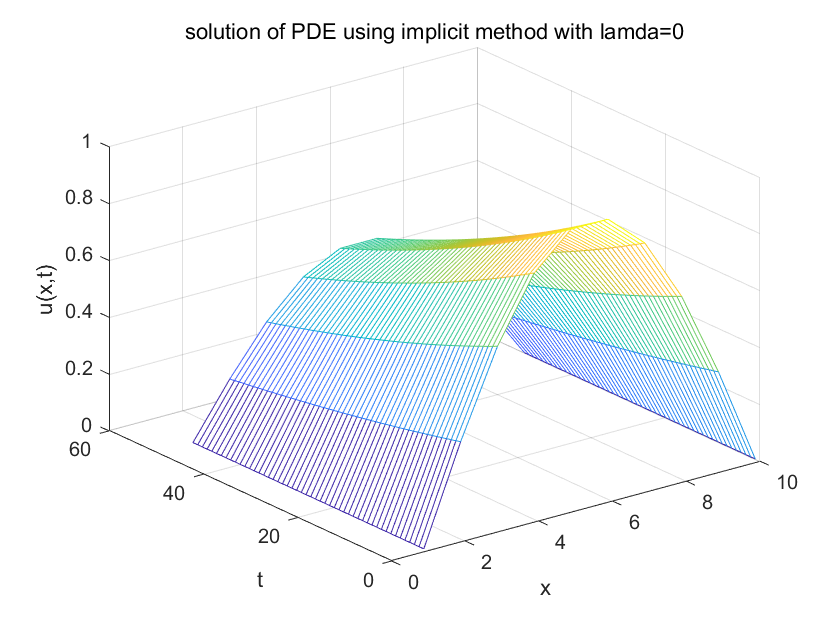

%plot
mesh(u_c0)
title('solution of PDE using implicit method with lamda=0')
xlabel('x')
ylabel('t')
zlabel('u(x,t)')


lam=1/4;
[ck025,u_c025]=imp(N,M,lam,u_c,R);
%show the coefficient martix with lamda=1/4
coe_matrix_lam_025=ck025

coe_matrix_lam_025 =     1.0500   -0.0250         0         0         0         0         0         0         0
   -0.0250    1.0500   -0.0250         0         0         0         0         0         0
         0   -0.0250    1.0500   -0.0250         0         0         0         0         0
         0         0   -0.0250    1.0500   -0.0250         0         0         0         0
         0         0         0   -0.0250    1.0500   -0.0250         0         0         0
         0         0         0         0   -0.0250    1.0500   -0.0250         0         0
         0         0         0         0         0   -0.0250    1.0500   -0.0250         0
         0         0         0         0         0         0   -0.0250    1.0500   -0.0250
         0         0         0         0         0         0         0   -0.0250    1.0500


%show the solution with lamda=1/4
solution_lam_025=u_c025

solution_lam_025 =          0    0.3420    0.6428    0.8660    0.9848    0.9848    0.8660    0.6428    0.3420    0.0000
    0.0080    0.3381    0.6351    0.8556    0.9730    0.9730    0.8556    0.6351    0.3379         0
    0.0080    0.3348    0.6275    0.8453    0.9613    0.9613    0.8453    0.6274    0.3338         0
    0.0079    0.3313    0.6200    0.8352    0.9497    0.9497    0.8352    0.6199    0.3298         0
    0.0078    0.3278    0.6127    0.8251    0.9383    0.9383    0.8251    0.6124    0.3259         0
    0.0077    0.3243    0.6055    0.8152    0.9270    0.9270    0.8152    0.6051    0.3219         0
    0.0076    0.3208    0.5984    0.8055    0.9159    0.9159    0.8054    0.5978    0.3181         0
    0.0076    0.3172    0.5913    0.7958    0.9049    0.9048    0.7957    0.5906    0.3142         0
    0.0075    0.3137    0.5844    0.7863    0.8940    0.8940    0.7861    0.5835    0.3105         0
    0.0074    0.3101    0.5775    0.7769    0.8833    0.8832    0.7767  

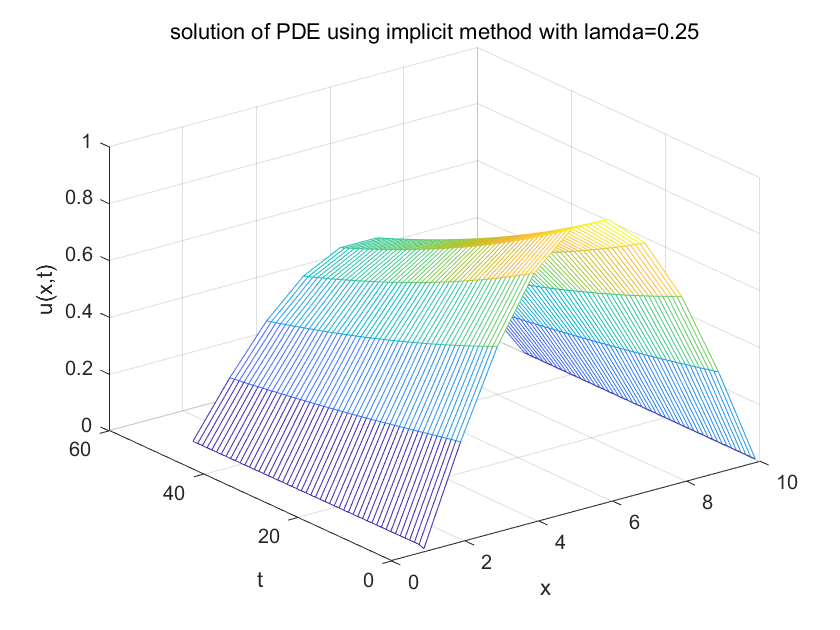

%plot
mesh(u_c025)
title('solution of PDE using implicit method with lamda=0.25')
xlabel('x')
ylabel('t')
zlabel('u(x,t)')



lam=0.5;
[ck05,u_c05]=imp(N,M,lam,u_c,R);
%show the coefficient martix with lamda=1/2
coe_matrix_lam_05=ck05

coe_matrix_lam_05 =     1.1000   -0.0500         0         0         0         0         0         0         0
   -0.0500    1.1000   -0.0500         0         0         0         0         0         0
         0   -0.0500    1.1000   -0.0500         0         0         0         0         0
         0         0   -0.0500    1.1000   -0.0500         0         0         0         0
         0         0         0   -0.0500    1.1000   -0.0500         0         0         0
         0         0         0         0   -0.0500    1.1000   -0.0500         0         0
         0         0         0         0         0   -0.0500    1.1000   -0.0500         0
         0         0         0         0         0         0   -0.0500    1.1000   -0.0500
         0         0         0         0         0         0         0   -0.0500    1.1000


%show the solution with lamda=1/2
solution_lam_05=u_c05

solution_lam_05 =          0    0.3420    0.6428    0.8660    0.9848    0.9848    0.8660    0.6428    0.3420    0.0000
    0.0154    0.3386    0.6351    0.8556    0.9730    0.9730    0.8556    0.6351    0.3379         0
    0.0153    0.3358    0.6276    0.8454    0.9613    0.9613    0.8454    0.6275    0.3339         0
    0.0151    0.3329    0.6203    0.8353    0.9498    0.9498    0.8352    0.6199    0.3299         0
    0.0150    0.3298    0.6131    0.8253    0.9384    0.9384    0.8252    0.6125    0.3259         0
    0.0148    0.3266    0.6061    0.8155    0.9272    0.9272    0.8153    0.6052    0.3220         0
    0.0147    0.3233    0.5991    0.8058    0.9161    0.9161    0.8056    0.5979    0.3181         0
    0.0145    0.3200    0.5922    0.7962    0.9051    0.9051    0.7959    0.5907    0.3143         0
    0.0144    0.3167    0.5854    0.7868    0.8943    0.8942    0.7864    0.5837    0.3106         0
    0.0142    0.3133    0.5787    0.7774    0.8836    0.8835    0.7769   

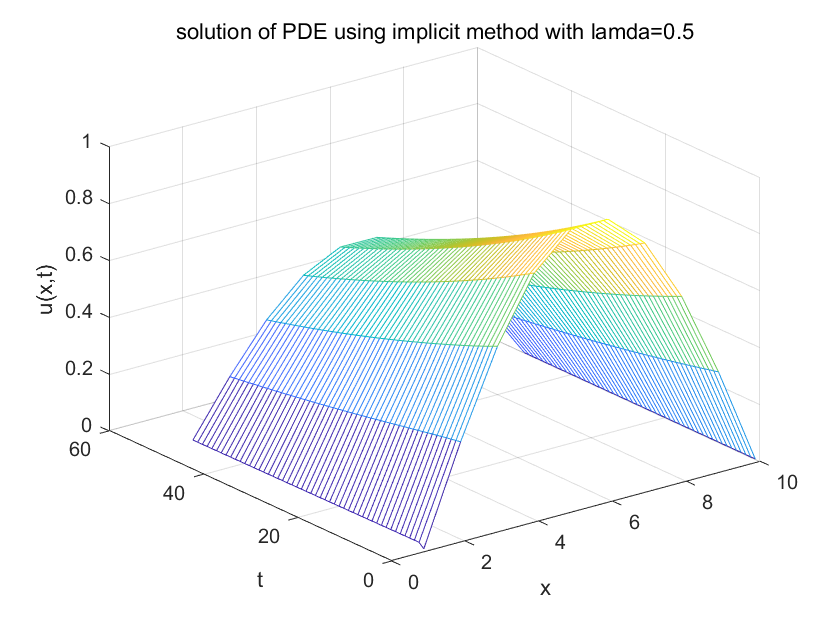

%plot
mesh(u_c05)
title('solution of PDE using implicit method with lamda=0.5')
xlabel('x')
ylabel('t')
zlabel('u(x,t)')


lam=3/4;
[ck075,u_c075]=imp(N,M,lam,u_c,R);
%show the coefficient martix with lamda=3/4
coe_matrix_lam_075=ck075

coe_matrix_lam_075 =     1.1500   -0.0750         0         0         0         0         0         0         0
   -0.0750    1.1500   -0.0750         0         0         0         0         0         0
         0   -0.0750    1.1500   -0.0750         0         0         0         0         0
         0         0   -0.0750    1.1500   -0.0750         0         0         0         0
         0         0         0   -0.0750    1.1500   -0.0750         0         0         0
         0         0         0         0   -0.0750    1.1500   -0.0750         0         0
         0         0         0         0         0   -0.0750    1.1500   -0.0750         0
         0         0         0         0         0         0   -0.0750    1.1500   -0.0750
         0         0         0         0         0         0         0   -0.0750    1.1500


%show the solution with lamda=3/4
solution_lam_075=u_c075

solution_lam_075 =          0    0.3420    0.6428    0.8660    0.9848    0.9848    0.8660    0.6428    0.3420    0.0000
    0.0221    0.3394    0.6352    0.8557    0.9730    0.9730    0.8557    0.6351    0.3379         0
    0.0220    0.3370    0.6278    0.8455    0.9614    0.9614    0.8454    0.6275    0.3339         0
    0.0218    0.3344    0.6206    0.8354    0.9499    0.9499    0.8353    0.6200    0.3299         0
    0.0216    0.3317    0.6136    0.8255    0.9386    0.9386    0.8254    0.6126    0.3260         0
    0.0214    0.3288    0.6067    0.8157    0.9274    0.9273    0.8155    0.6053    0.3221         0
    0.0212    0.3257    0.5999    0.8061    0.9163    0.9163    0.8057    0.5980    0.3182         0
    0.0210    0.3227    0.5931    0.7966    0.9054    0.9053    0.7961    0.5909    0.3144         0
    0.0208    0.3195    0.5865    0.7872    0.8946    0.8945    0.7866    0.5838    0.3107         0
    0.0206    0.3163    0.5799    0.7780    0.8840    0.8838    0.7772  

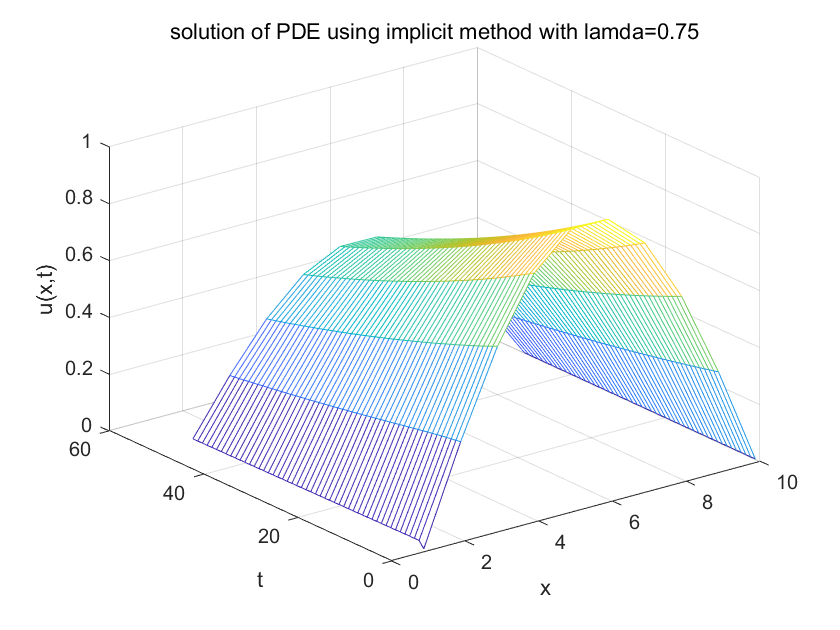

%plot
mesh(u_c075)
title('solution of PDE using implicit method with lamda=0.75')
xlabel('x')
ylabel('t')
zlabel('u(x,t)')


lam=1;
[ck1,u_c1]=imp(N,M,lam,u_c,R);
%show the coefficient martix with lamda=1
coe_matrix_lam_1=ck1

coe_matrix_lam_1 =     1.2000   -0.1000         0         0         0         0         0         0         0
   -0.1000    1.2000   -0.1000         0         0         0         0         0         0
         0   -0.1000    1.2000   -0.1000         0         0         0         0         0
         0         0   -0.1000    1.2000   -0.1000         0         0         0         0
         0         0         0   -0.1000    1.2000   -0.1000         0         0         0
         0         0         0         0   -0.1000    1.2000   -0.1000         0         0
         0         0         0         0         0   -0.1000    1.2000   -0.1000         0
         0         0         0         0         0         0   -0.1000    1.2000   -0.1000
         0         0         0         0         0         0         0   -0.1000    1.2000


%show the solution with lamda=1
solution_lam_1=u_c1

solution_lam_1 =          0    0.3420    0.6428    0.8660    0.9848    0.9848    0.8660    0.6428    0.3420    0.0000
    0.0284    0.3403    0.6353    0.8557    0.9731    0.9731    0.8557    0.6351    0.3379         0
    0.0282    0.3383    0.6281    0.8456    0.9615    0.9615    0.8455    0.6276    0.3339         0
    0.0280    0.3360    0.6210    0.8356    0.9500    0.9500    0.8354    0.6201    0.3299         0
    0.0278    0.3335    0.6141    0.8257    0.9387    0.9387    0.8255    0.6127    0.3260         0
    0.0276    0.3308    0.6073    0.8160    0.9276    0.9275    0.8156    0.6054    0.3221         0
    0.0273    0.3280    0.6007    0.8064    0.9165    0.9165    0.8059    0.5982    0.3183         0
    0.0271    0.3251    0.5941    0.7970    0.9057    0.9056    0.7963    0.5910    0.3145         0
    0.0268    0.3221    0.5875    0.7877    0.8949    0.8948    0.7868    0.5840    0.3107         0
    0.0266    0.3191    0.5811    0.7785    0.8843    0.8841    0.7775    

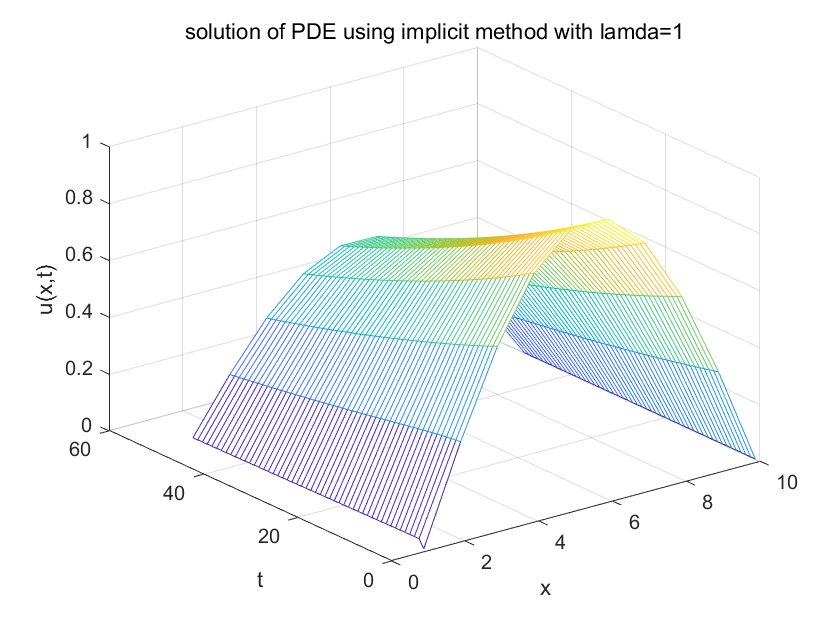

%plot
mesh(u_c1)
title('solution of PDE using implicit method with lamda=1')
xlabel('x')
ylabel('t')
zlabel('u(x,t)')

And if we plot the solution of t=0.05 together

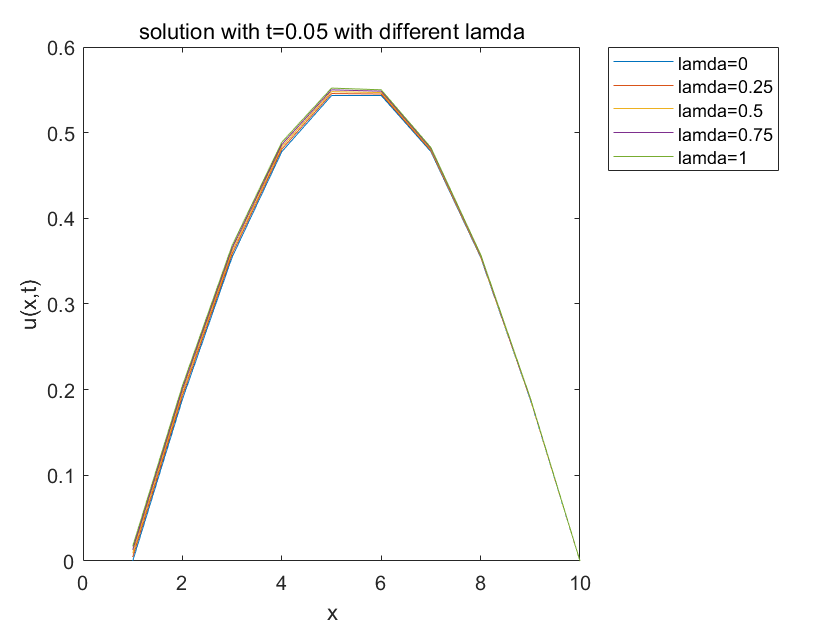

plot(solution_lam_0(end,:))
hold on
plot(solution_lam_025(end,:))
plot(solution_lam_05(end,:))
plot(solution_lam_075(end,:))
plot(solution_lam_1(end,:))
hold off
legend('lamda=0','lamda=0.25','lamda=0.5','lamda=0.75','lamda=1')
title('solution with t=0.05 with different lamda')
xlabel('x')
ylabel('u(x,t)')

And recall the true solution

$u\left(x,t\right)=\sin \left(\pi x\right)e^{-\pi^2 t}$        (18)

and plot it with t=0.05

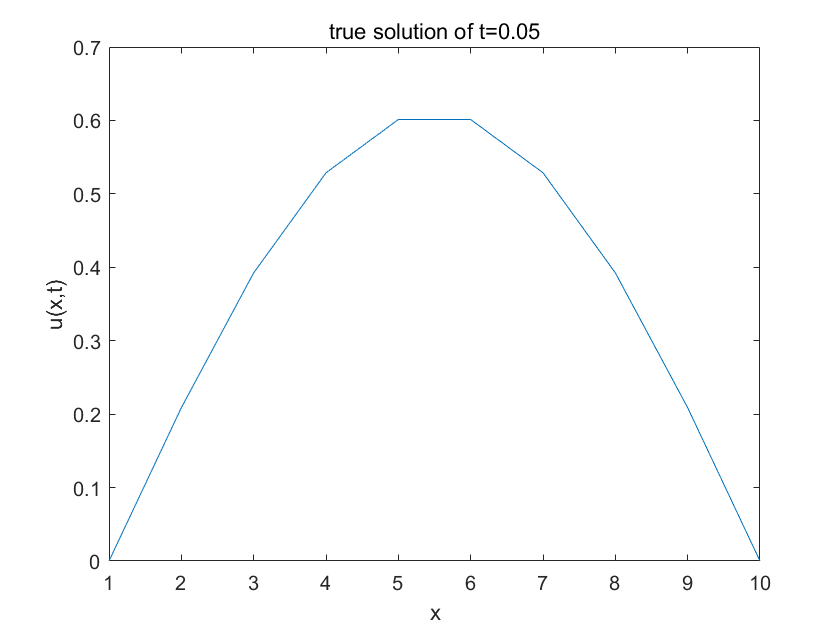

x=linspace(0,1,N);
[ut]=u_true(x,0.05);%compute the true value
plot(ut)
title('true solution of t=0.05')
xlabel('x')
ylabel('u(x,t)')

ANd if we plot from t=0 to t=0.05

t=linspace(0,pp,M);
[xx,tt]=meshgrid(x,t);
[ut2]=u_true(xx,tt)%compute the true value

ut2 =          0    0.3420    0.6428    0.8660    0.9848    0.9848    0.8660    0.6428    0.3420    0.0000
         0    0.3386    0.6363    0.8573    0.9749    0.9749    0.8573    0.6363    0.3386    0.0000
         0    0.3352    0.6300    0.8488    0.9652    0.9652    0.8488    0.6300    0.3352    0.0000
         0    0.3318    0.6237    0.8403    0.9555    0.9555    0.8403    0.6237    0.3318    0.0000
         0    0.3285    0.6174    0.8318    0.9459    0.9459    0.8318    0.6174    0.3285    0.0000
         0    0.3252    0.6112    0.8235    0.9364    0.9364    0.8235    0.6112    0.3252    0.0000
         0    0.3220    0.6051    0.8152    0.9271    0.9271    0.8152    0.6051    0.3220    0.0000
         0    0.3187    0.5990    0.8071    0.9178    0.9178    0.8071    0.5990    0.3187    0.0000
         0    0.3155    0.5930    0.7990    0.9086    0.9086    0.7990    0.5930    0.3155    0.0000
         0    0.3124    0.5871    0.7910    0.8995    0.8995    0.7910    0.5871    0

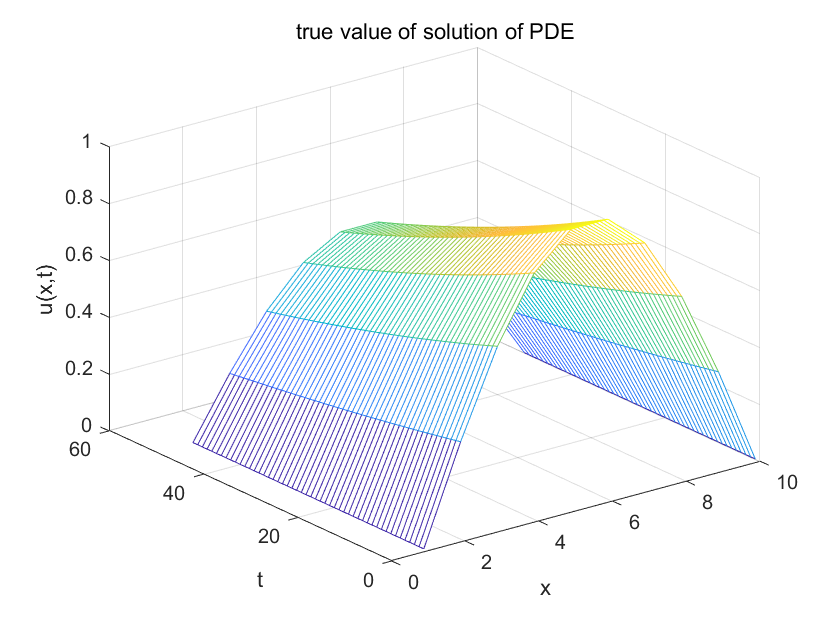

mesh(ut2)
title('true value of solution of PDE')
xlabel('x')
ylabel('t')
zlabel('u(x,t)')

function [ut]=u_true(x,t)
%funtion of equation (17)
   ut=sin(pi*x).*exp(-pi^2.*t); 
end

function [p]=p(lam,r,u,n)
%function of compute P_j
%input lamda, r: the ratio K/H^2, u: initial condition, n
%output vector P
    for i=2:n-1
        %compute P_2 to P_n-1
        p(i)=r*(1-lam)*u(1,i+1)+(1-2*r*(1-lam))*u(1,i)+r*(1-lam)*u(1,i-1);
    end
end

function [N,M,R,u_c]=inti(H,K,pp)
%function of general initial condition
%with input H K and p out put :
%N number of grid point x direction has
%M number of grid point t direction has
%R the ratio of K/H^2
%u_c the matrix contain the initial condition
    N=1/H+1;
    M=pp/K+1;
    R=K/(H*H);
    M=M-1;
    N=N-1;
    x=linspace(0,1,N);
    u=zeros(M,N);
    u(1,:)=sin(pi*x);%set boundary condition
    u_c=u;
end

function [ck]=coeMatrix(lam,N,R)
%compute Coefiicient Matrix K 
    v=ones(N-1,1)*(1+2*R*lam);%general 1+2r*lamda
    ck=diag(v);%diagonalize the 1+2r*lamda
    cv=ones(N-2,1)*(-lam*R);%general -lamda*r
    pc=diag(cv,1);%diagonalize the -lamda*r on and line up diagonal
    pc=pc+pc';%also set the line down diagonal -lamda*r
    ck=ck+pc;%combine -lamda*r and 1+2r*lamda together.
end

function [ck,u_c]=imp(N,M,lam,u_c,R)
%function of compute the solution Coefiicient Matrix
    ck=coeMatrix(lam,N,R);%load Coefiicient Matrix
    for l=1:M-1
        %loop for i
        P1=p(lam,R,u_c(l,:),N);%compute P_j with different i
        u_c(l+1,1:N-1)=ck\P1';
        %compute the solution and store the vector into a matrix line by line
    end
end